# Tutorial on color matching and display rendering

This tutorial explains how to use ISETCam to

- compute the XYZ values of a light source

- set a monitor output to achieve these XYZ levels

- manage the nonlinear relationship between frame buffer and emitted light output 

- compute and plot the xy chromaticity values of a display

This tutorial was initially used to teach Psych 221.  More detailed tutorials are available in the psych221 repository on GitHub.

ieInit;

## Computing XYZ values of a monitor

We must measure the main functions that define the color properties of any display: these are the phosphor spectral power distributions (SPDs). We measure these functions using a spectral radiometer, a device that measures the power per nanometer emitted by the display.

The spectral power distributions of a monitor in my lab, measured when the monitor display intensity was set to full value, are stored in columns of the matrix called "phosphors". This matrix is stored in the data file below

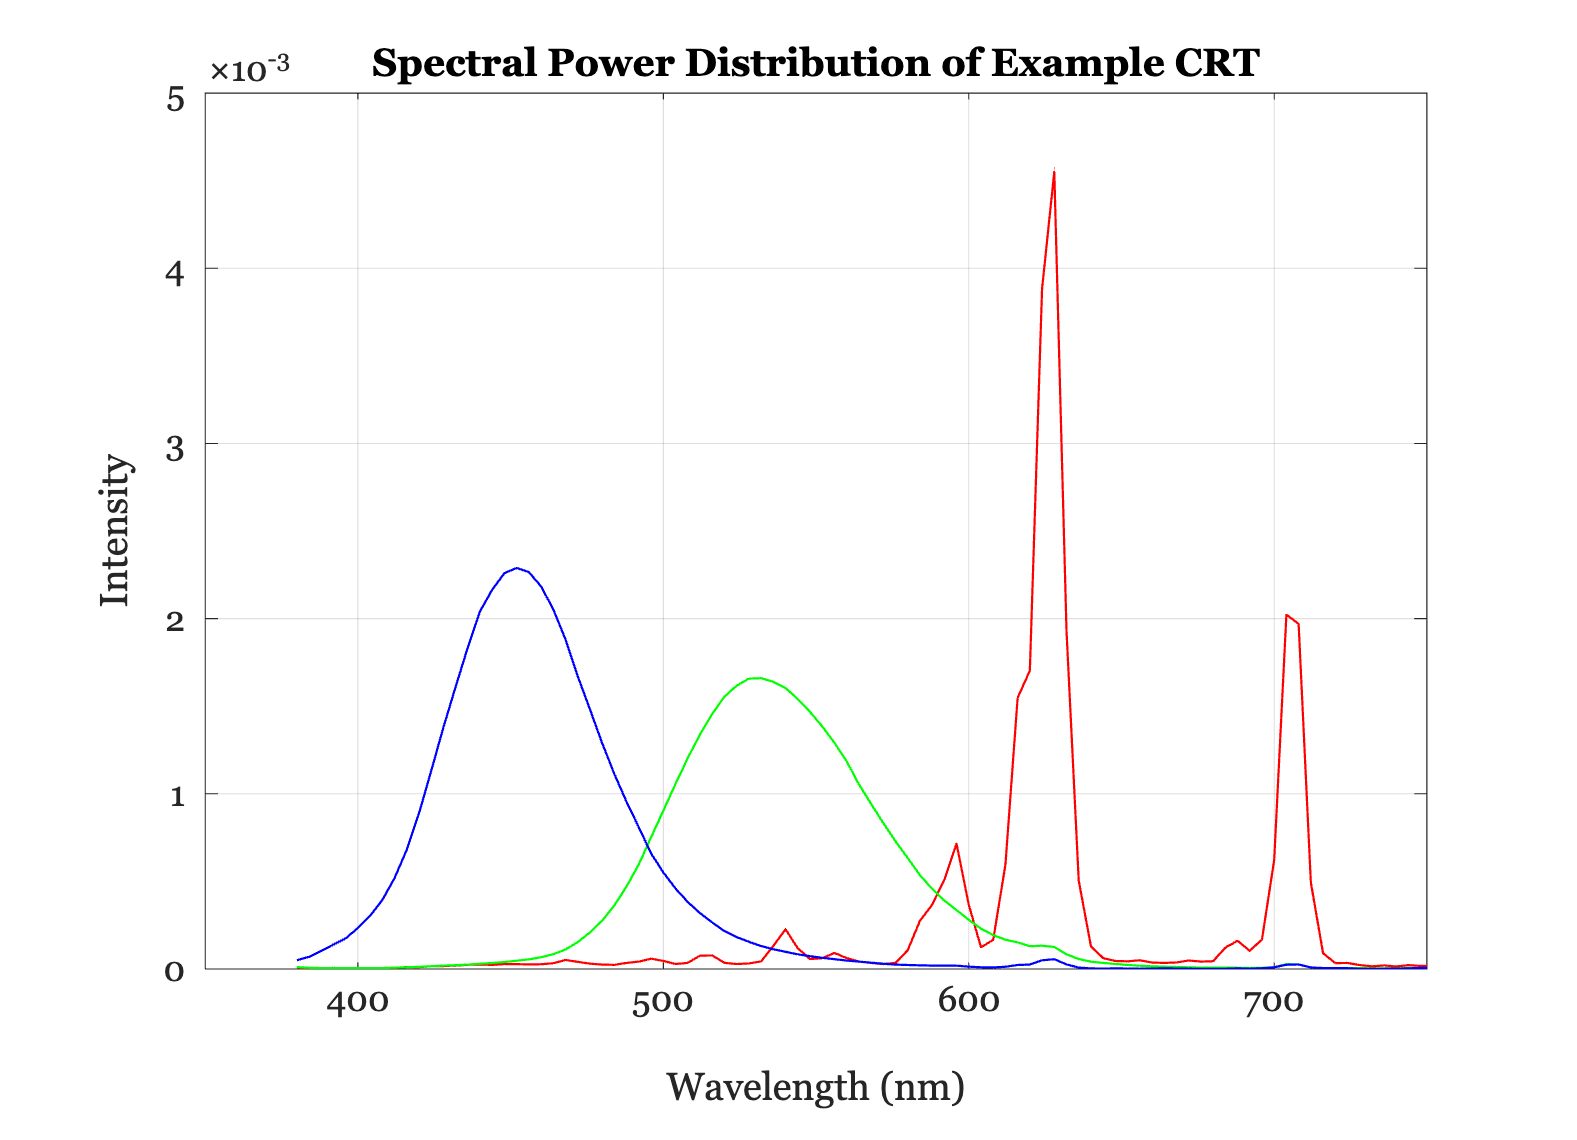

% Read in a display
d = displayCreate('CRT-Dell');
phosphors  = displayGet(d,'spd');
wavelength = displayGet(d,'wave');

% Plot the display phosphors
ieNewGraphWin;
plot(wavelength,phosphors(:,1),'r-', ...
    wavelength,phosphors(:,2), 'g-',...
    wavelength,phosphors(:,3),'b-')
xlabel('Wavelength (nm)'), ylabel('Intensity')
title('Spectral Power Distribution of Example CRT');
set(gca,'xlim',[350 750]), grid on

To measure the XYZ values of these phosphors, we load in the xbar,ybar, zbar functions defined by the CIE.  These are also stored in the columns of a matrix, called xyz.  Because these functions are so widely used, they are stored in the main toolbox area.

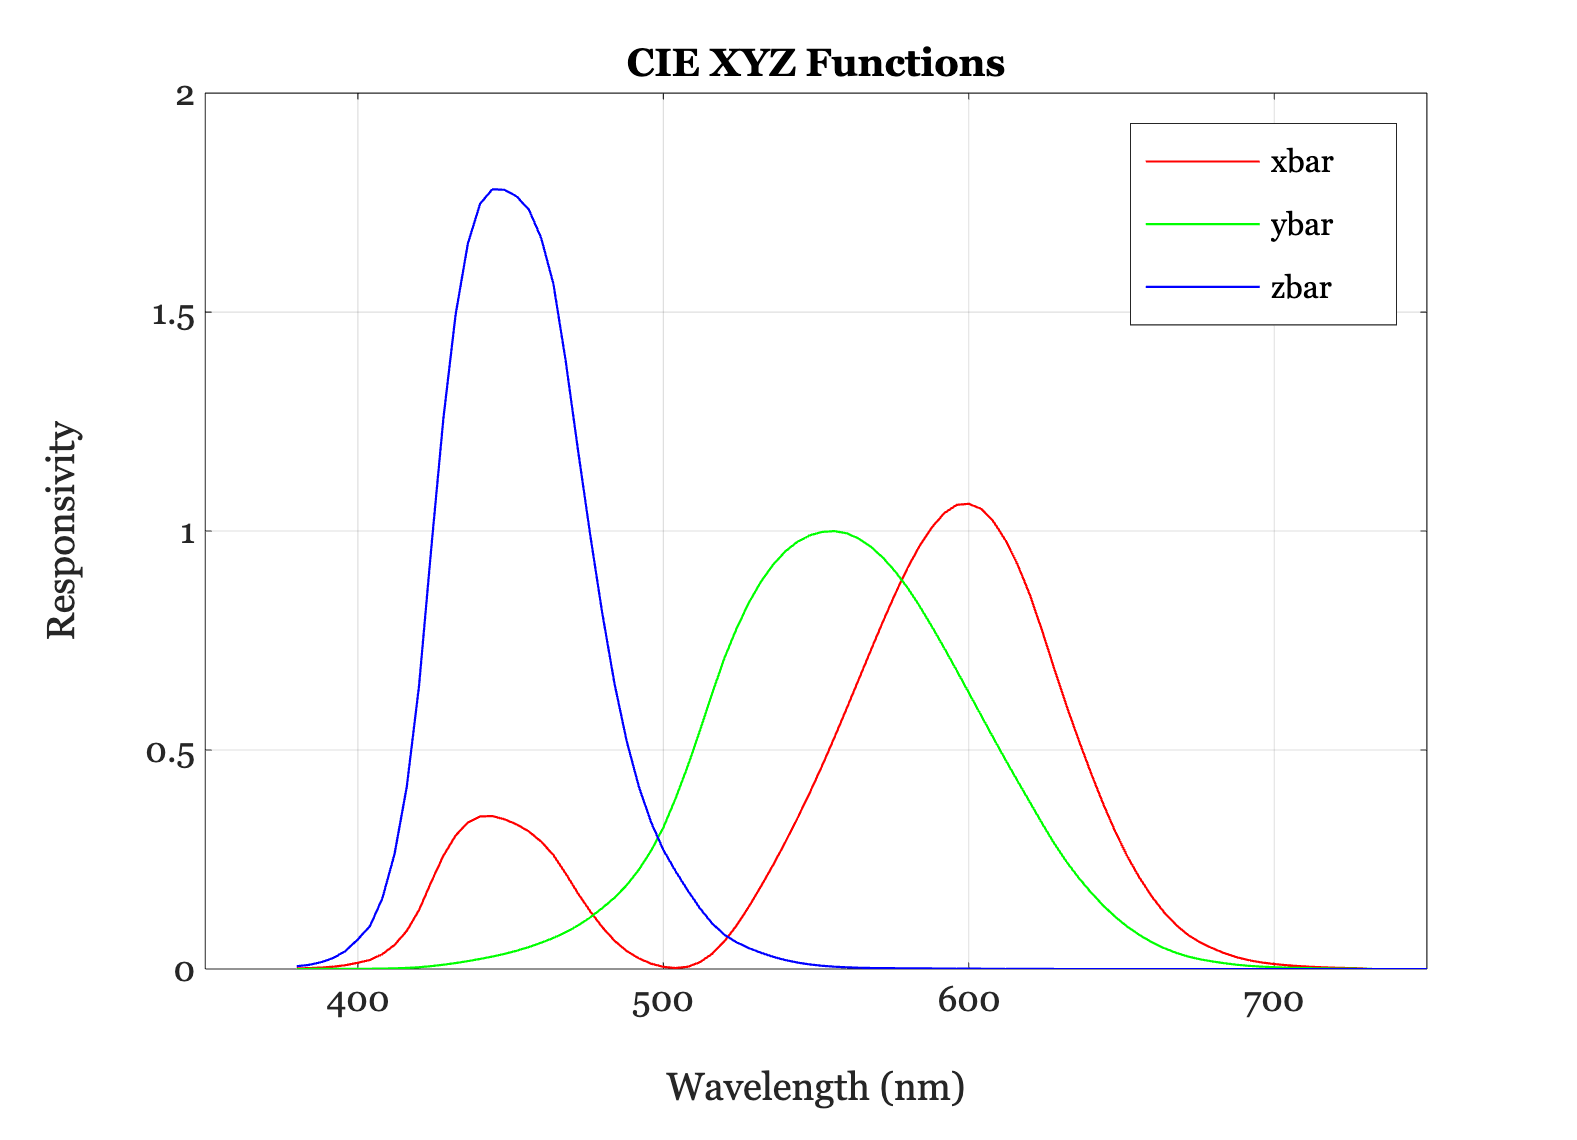

ieNewGraphWin;
XYZ = ieReadSpectra('XYZ',wavelength);
plot(wavelength, XYZ(:,1:3));
xlabel('Wavelength (nm)'), ylabel('Responsivity')
legend('xbar','ybar','zbar');
title('CIE XYZ Functions');
set(gca,'xlim',[350 750]), grid on

To compute the (X,Y,Z) values of each of the phosphors by multiplying the phosphor matrix times the xyz matrix. Notice that the phosphors are in the columns of the matrix on the right, and the xbar,ybar,zbar functions are in the rows of the matrix on the left.

maxXYZ = XYZ'*phosphors

maxXYZ =     0.0144    0.0117    0.0086
    0.0079    0.0246    0.0044
    0.0008    0.0040    0.0450


This calculation doesn't take into account the proper constants and details of the formula.  There is a routine that manages that for you.

maxXYZ = ieXYZFromEnergy(phosphors',wavelength(:));

% The luminance of each phosphor is given by the Y values.  The
% maximum value is when the phosphors are set to maximum intensity.

maxXYZ(2,:)

ans =    31.9501   67.1483   11.0284


The total luminance the display can reach, with all three phosphors on, is given by the sum of these three values, 100 cd/m^2 is a typical luminance level for monitors.

sum(maxXYZ(2,:))

ans = 110.1268

## Using the CMFs to Match a target

Suppose that you send a space ship to the surface of Mars. The spaceship sends back a measurement of a spectral power distribution.  Let's load it up. This time we suppose the display is only calibrated from 400 to 700 in 5 nm steps.

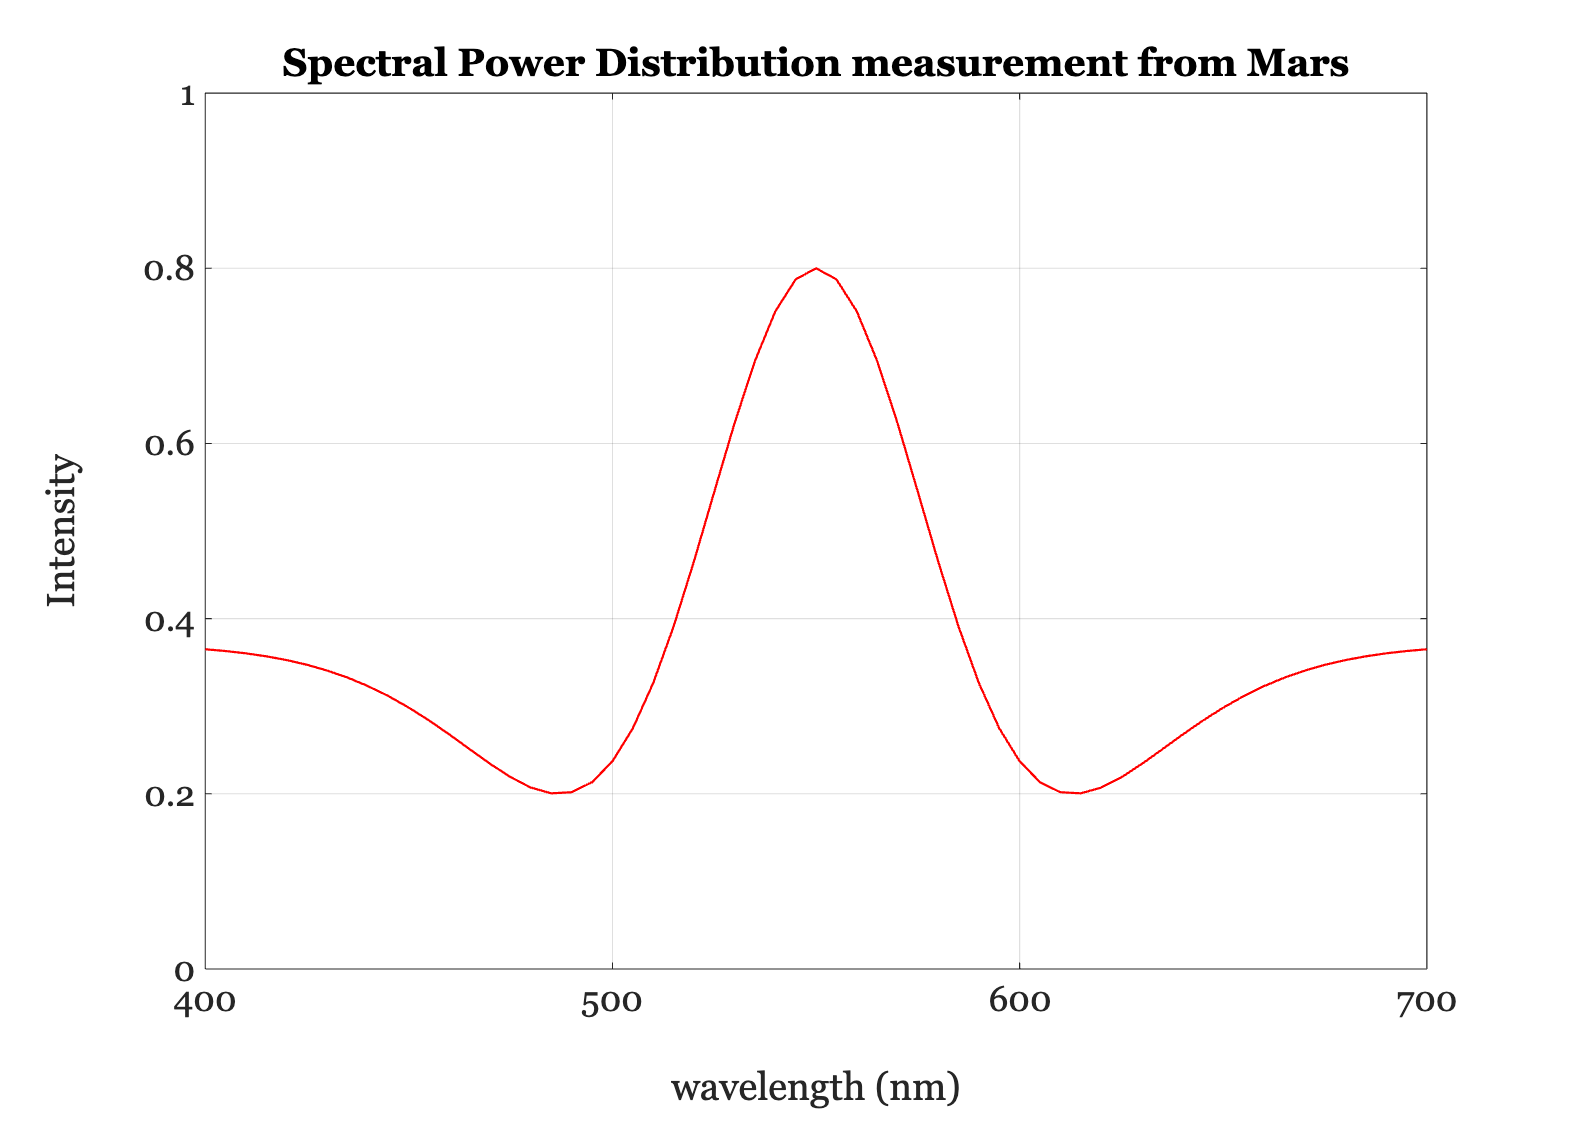

wavelength = 400:5:700;
d = displayCreate('CRT-Dell','wave',wavelength);
phosphors  = displayGet(d,'spd');
XYZ = ieReadSpectra('XYZ',wavelength);

marsSPD = ieReadSpectra('mars.mat',wavelength);
clf,plot(wavelength,marsSPD,'r-')
set(gca,'ylim',[0 1])
grid on, xlabel('wavelength (nm)'); ylabel('Intensity')
title('Spectral Power Distribution measurement from Mars');


% Now, how do we set the monitor intensities so that what we see on a
% display is a visual match to the spectrum measured on Mars?  We use the
% XYZ color-matching functions.  First, measure the values for the Martian
% spectrum
marsXYZ = ieXYZFromEnergy(marsSPD',wavelength(:));


Now, recall that the monitor color properties are determined by the relative intensity of the outputs of the monitor phosphor SPDs.  Suppose these  intensities are [r,g,b]'.  Then the monitor output is phosphors*[r,g,b]'.  For example, when the red phosphor only is on the spectrum is

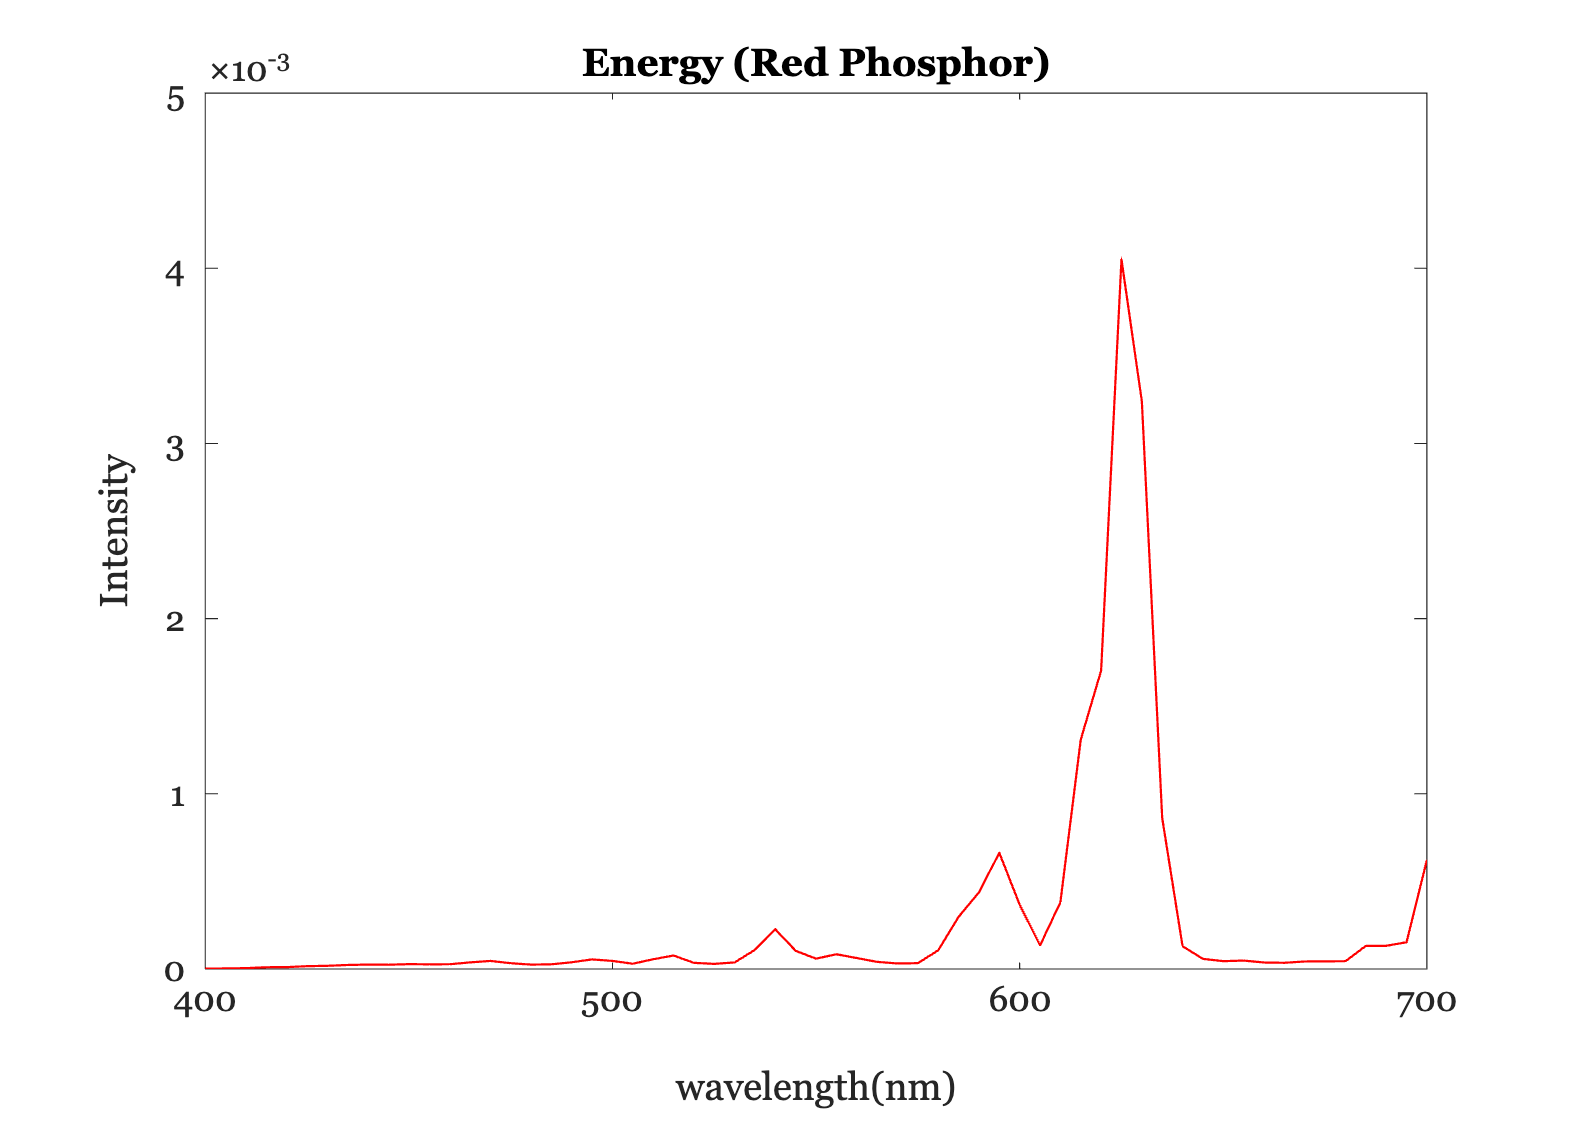

plot(wavelength, phosphors*[1 0 0]', 'r-');
xlabel('wavelength(nm)'); ylabel('Intensity')
title('Energy (Red Phosphor)');

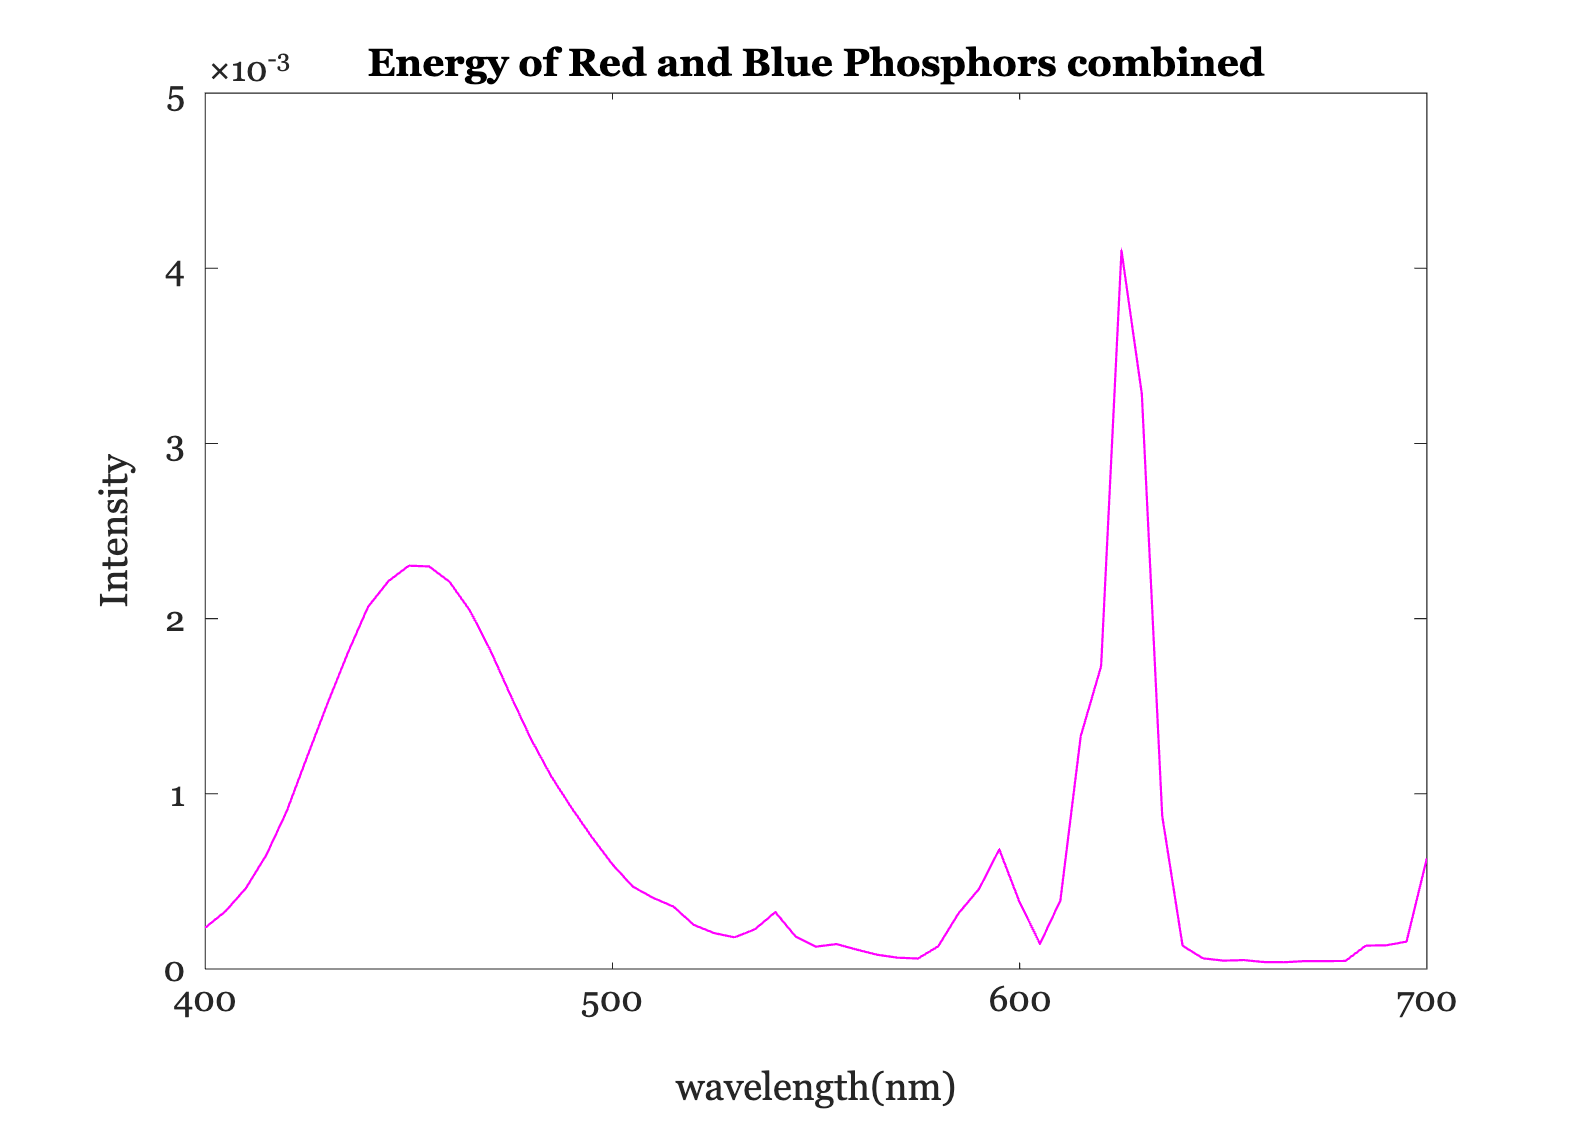


% When the red and blue are on, the output is

plot(wavelength, phosphors*[1 0 1]','m-');
xlabel('wavelength(nm)'); ylabel('Intensity')
title('Energy of Red and Blue Phosphors combined');


% To find the relationship between the [r,g,b] values and the monitor XYZ
% outputs, we only need to multiply the output times the XYZ functions.
% Hence, there is a matrix that maps the linear monitor intensities into
% the XYZ values.  This matrix is
%
RGB2XYZ = ieXYZFromEnergy(phosphors',wavelength)';


Take a look at this matrix and think about its entries.  Notice that the first column contains the XYZ values associated with the red phosphor, the middle with the green, and the third column is associated with the blue.  These values should make sense to you given the shapes of the XYZ functions we have already plotted.

Now, to represent the Martian spectrum on our display, we need to compute only one more thing.  How do we set the [r,g,b] values when we know the XYZ values of the spectrum?  For this, we need a matrix that converts XYZ to monitor linear gun intensities, the inverse of the matrix that we have.  So, we calculate this new matrix as

XYZ2RGB = inv(RGB2XYZ)

XYZ2RGB =     0.0349   -0.0158   -0.0052
   -0.0111    0.0201    0.0002
    0.0004   -0.0016    0.0082


marsRGB = XYZ2RGB*marsXYZ'

marsRGB =   279.6730
  423.2905
  130.1053



% This shows that the XYZ from the two energy values are the same XYZ.
ieXYZFromEnergy((phosphors*marsRGB)',wavelength)

ans = 1.0e+04 *

    2.7377    3.5904    2.1227


ieXYZFromEnergy(marsSPD',wavelength)

ans = 1.0e+04 *

    2.7377    3.5904    2.1227


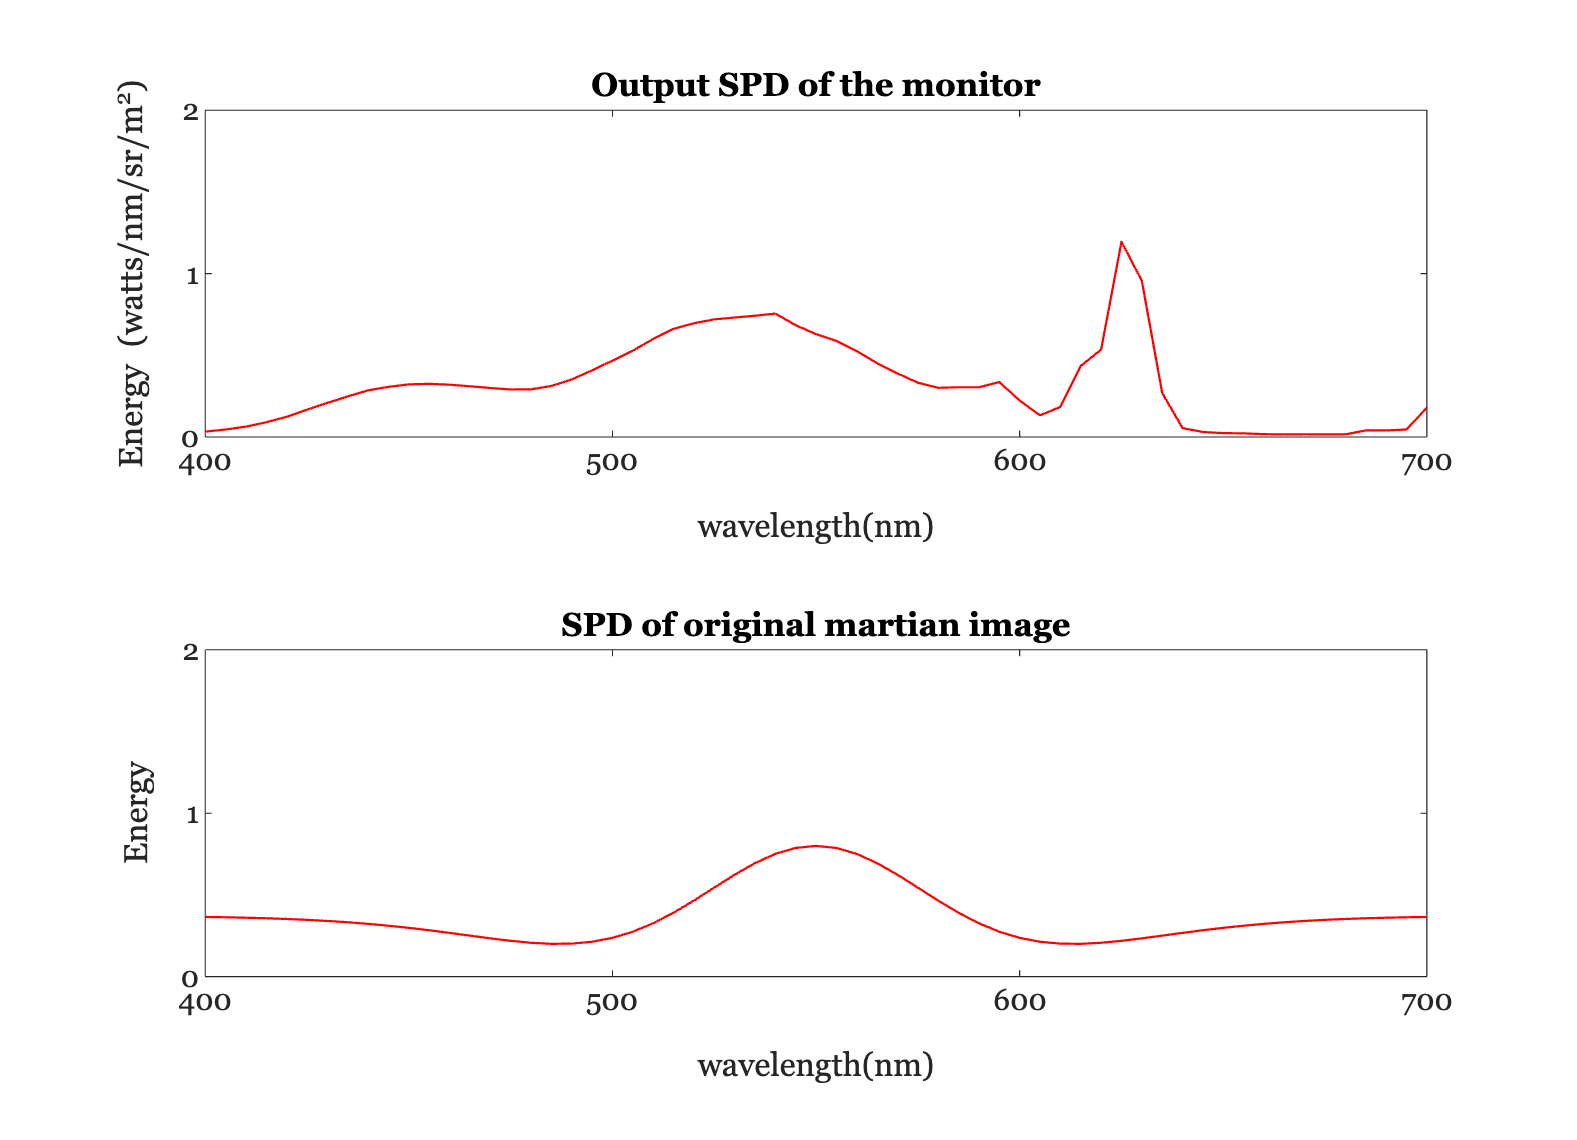


% The spectrum we should display, therefore, is equal to
ieNewGraphWin;
subplot(2,1,1)
plot(wavelength,phosphors*marsRGB)
title('Output SPD of the monitor');
set(gca,'ylim',[0 2])
xlabel('wavelength(nm)');ylabel('Energy (watts/nm/sr/m^2)')

% This will be a visual match to the spectrum
subplot(2,1,2)
plot(wavelength,marsSPD);
set(gca,'ylim',[0 2])
title('SPD of original martian image');
xlabel('wavelength(nm)');ylabel('Energy')

The principles are the same when we make a match on a normal monitor. The only difference, which is reviewed below, is that the frame-buffer entries and the intensity of the phosphor output are a nonlinearly related. Hence, we must set the frame-buffer entries so that we obtain the linear intensity outputs we have just calculated.  This process is called gamma correction.

## Managing a nonlinear display - Gamma tables and inverse gamma tables

The relationship between the intensity emitted by a CRT phosphor and the frame-buffer value is generally a nonlinear function. An example of the function relating frame-buffer value to emitted light intensity is shown here:

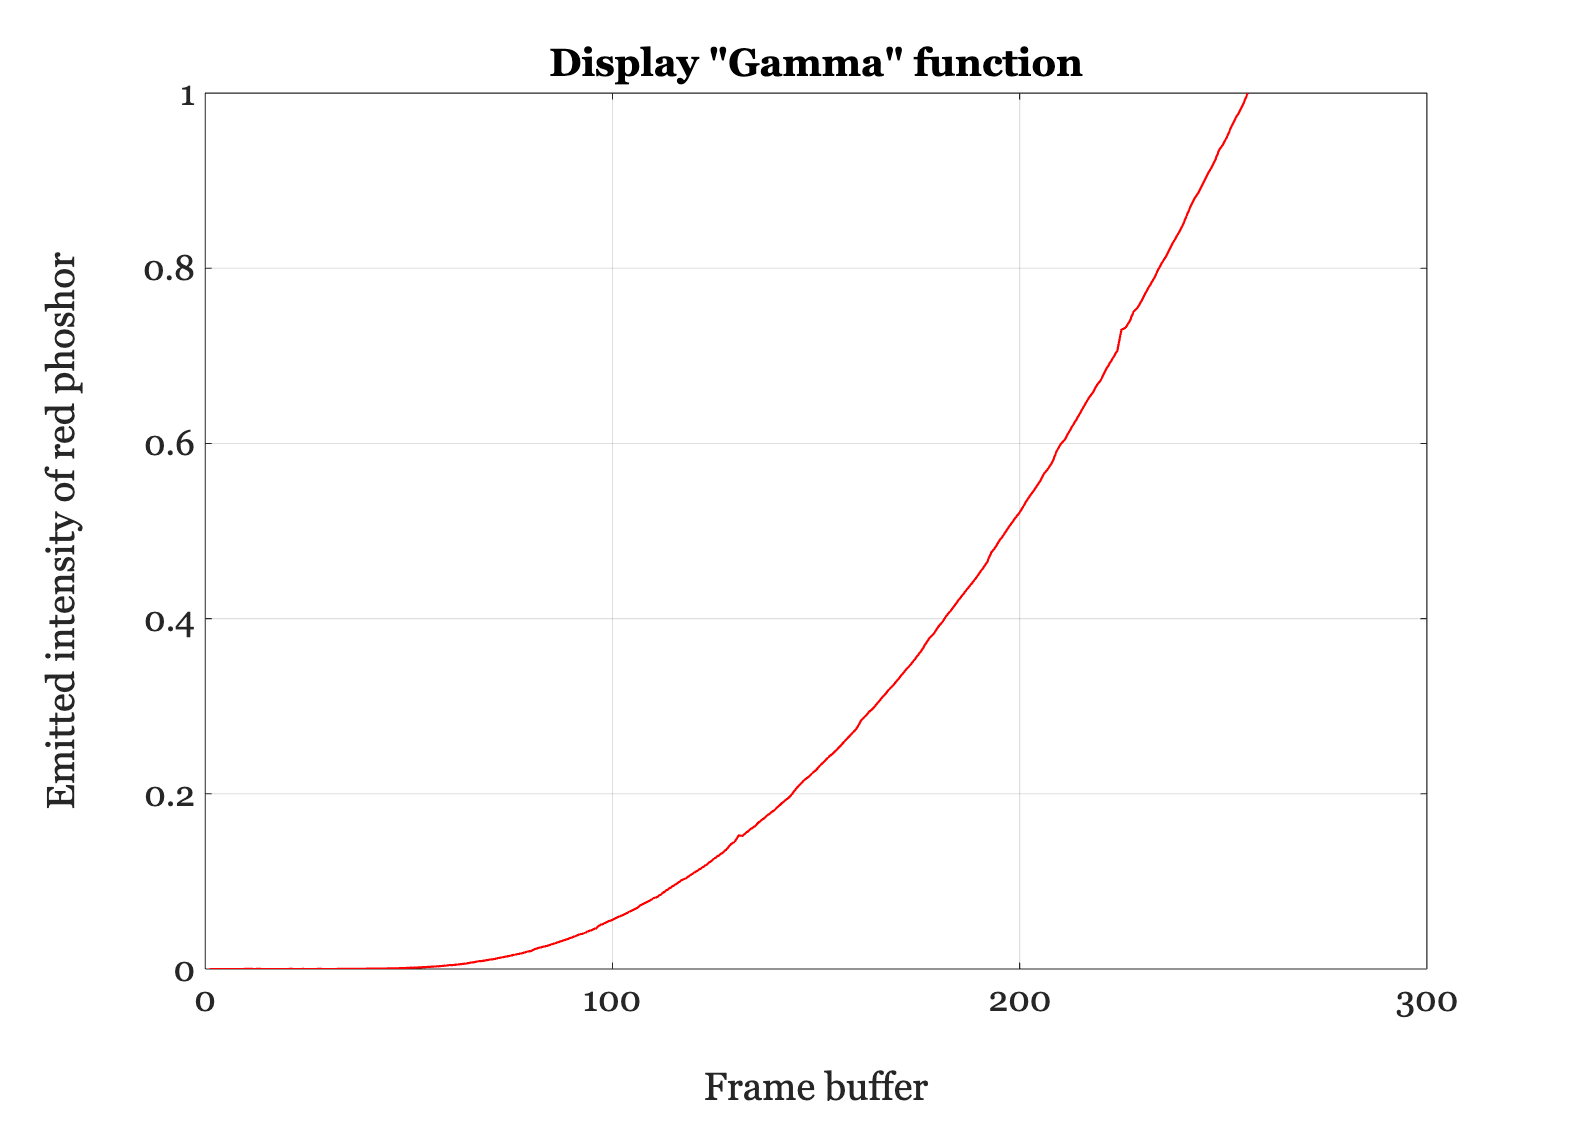

load cMatch/monitorGam
ieNewGraphWin;
plot(1:256,monitorGam(:,1)), grid on
xlabel('Frame buffer');
ylabel('Emitted intensity of red phoshor');
title('Display "Gamma" function')

This is called the "gamma" function of the display.  The reason for this title is that the function is roughly a simple power function and the exponent has historically been called "gamma." Here is a comparison of the gamma function of the red phosphor and a power function with an exponent of 2.2, the most common value.

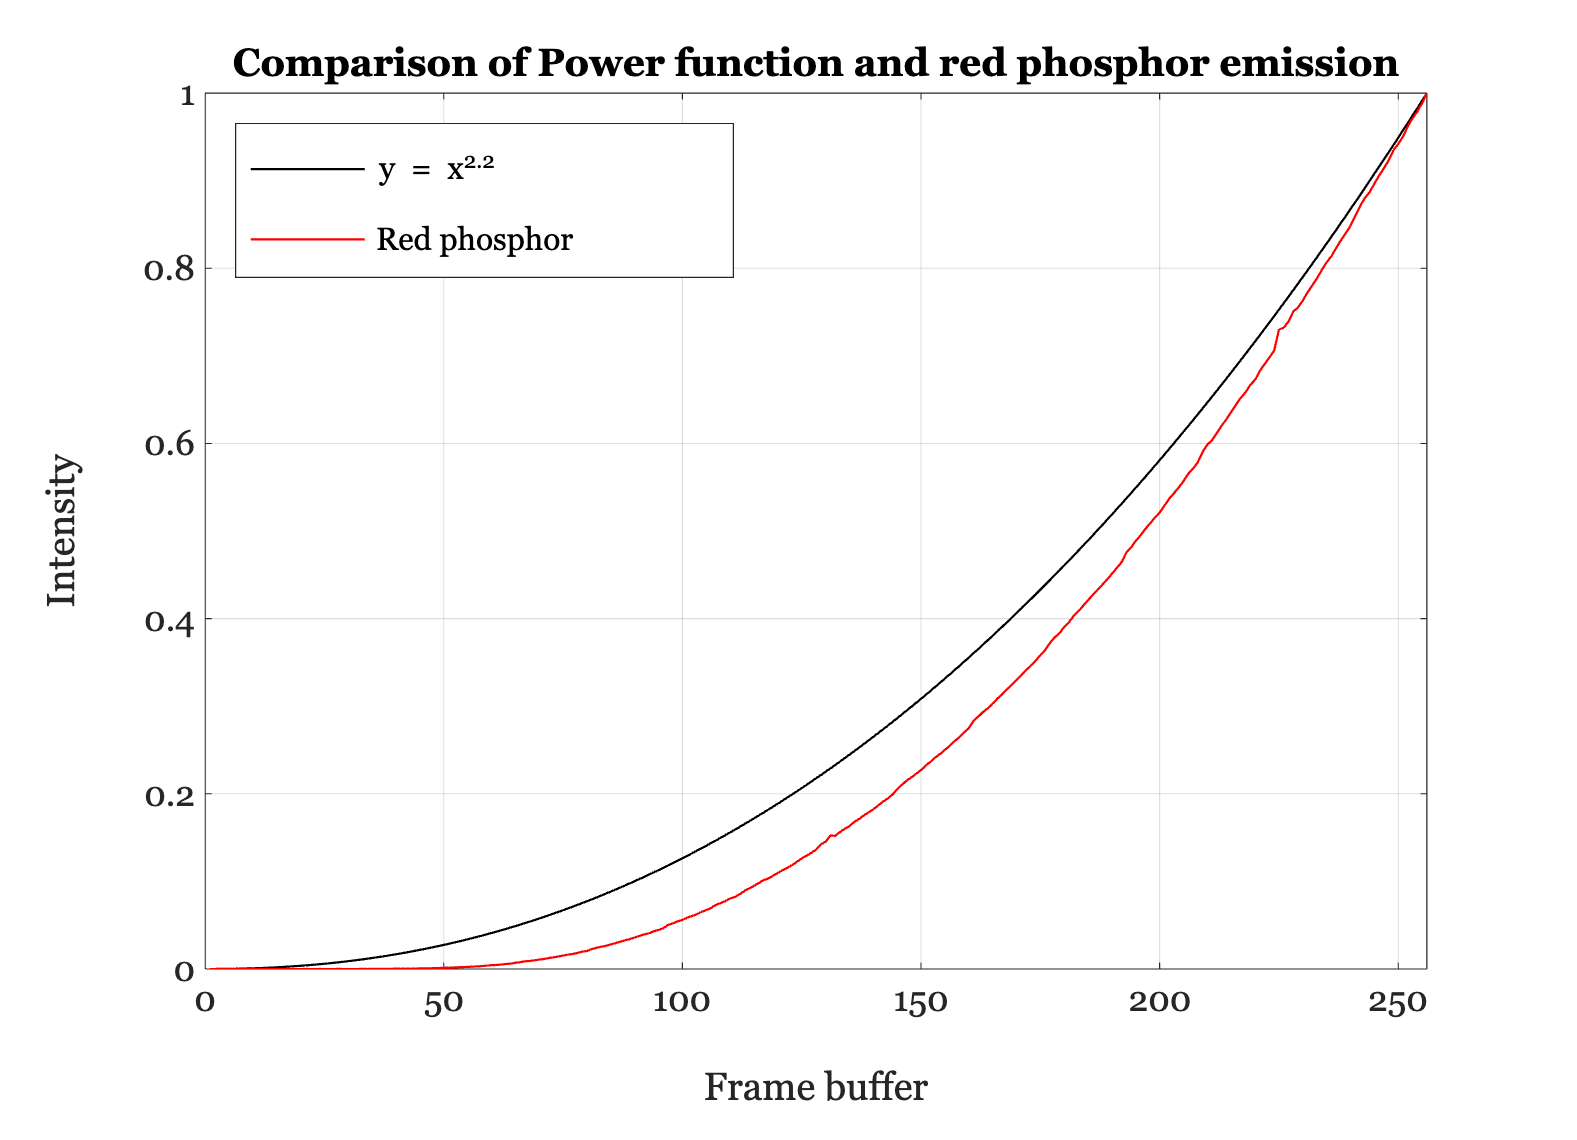

frameBuffer = 1:256;
pred = ((frameBuffer)/256).^(2.2);
plot(frameBuffer,pred,'k-',frameBuffer,monitorGam(:,1),'r-')
xlim([0 256]); xlabel('Frame buffer'); ylabel('Intensity');
title('Comparison of Power function and red phosphor emission')
legend('y = x^2^.^2', 'Red phosphor','Location', 'NorthWest');
grid on

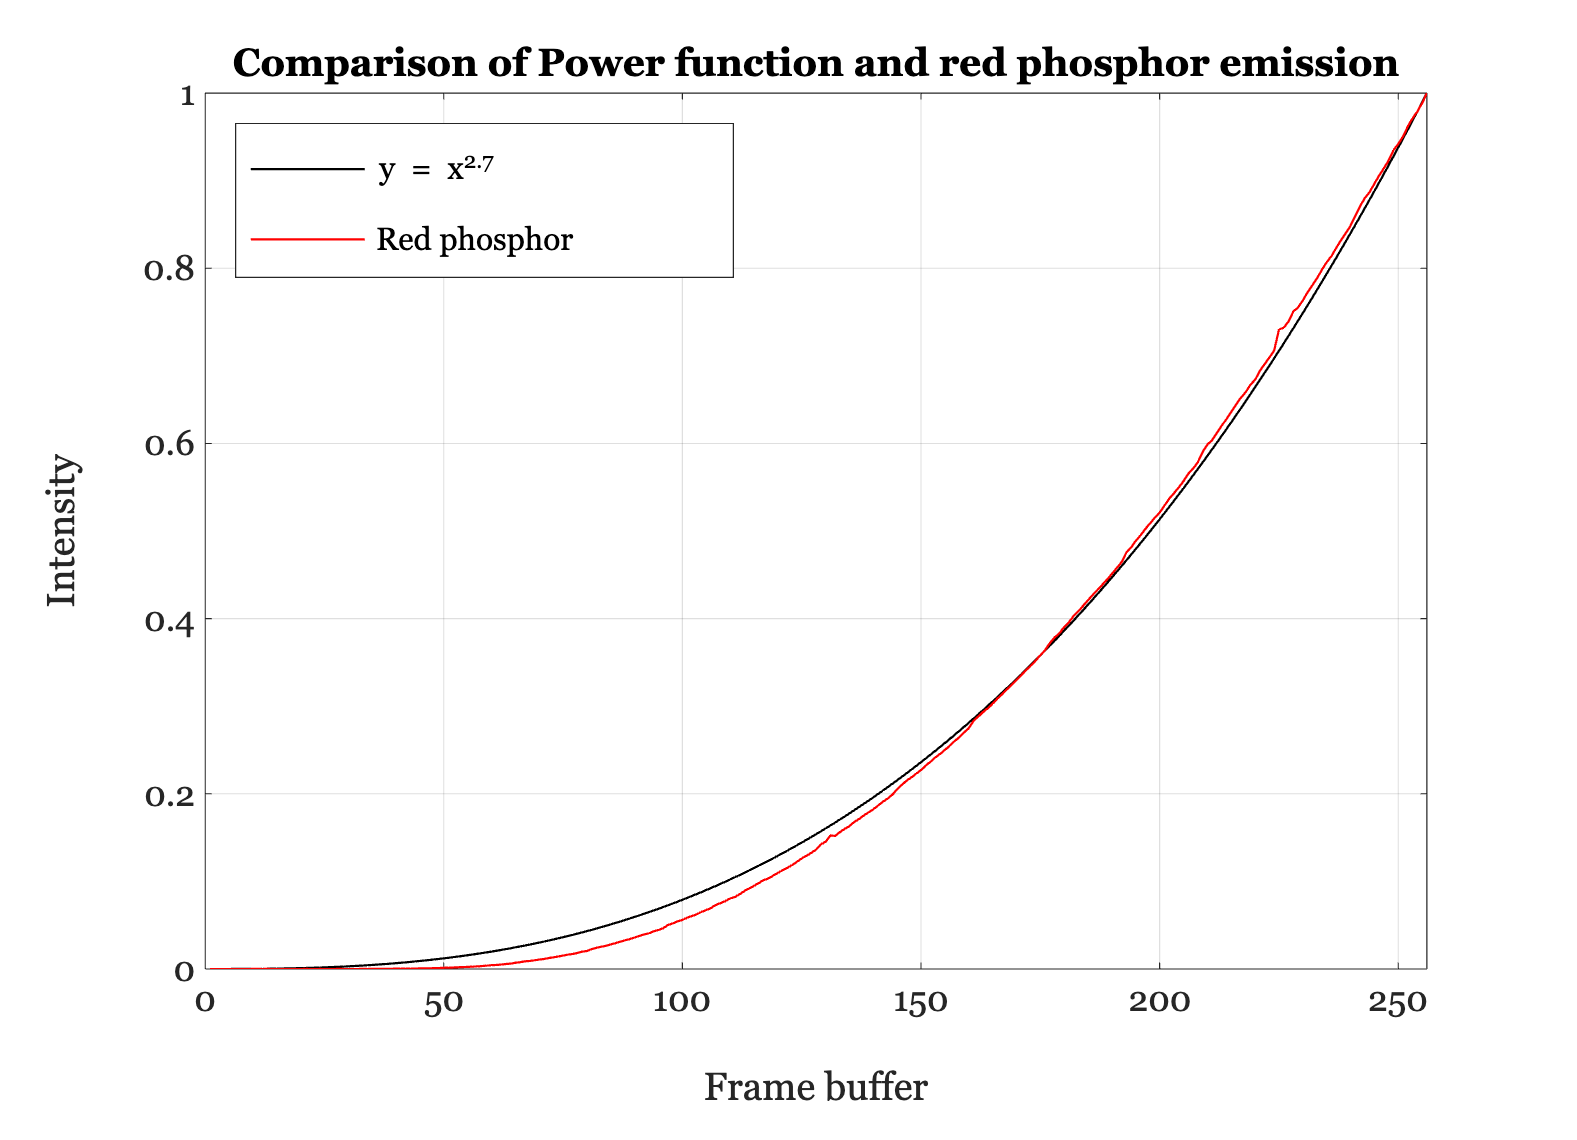


% For this display, you can see that the fit is much better using a larger
% exponent, namely

frameBuffer = 1:256;
pred = ((frameBuffer)/256).^(2.7);
plot(frameBuffer,pred,'k-',frameBuffer,monitorGam(:,1),'r-')
xlim([0 256]); xlabel('Frame buffer'); ylabel('Intensity');
title('Comparison of Power function and red phosphor emission')
legend('y = x^2^.^7', 'Red phosphor','Location', 'NorthWest');
grid on

Recall that we measured the emitted intensity using the maximum framebuffer value.  This corresponds to the column entries in phosphor, and these are the signals emitted when the relative intensity is one.

To specify the intensity of the emitted light for any given frame-buffer level,  we can use the simple gamma function.  For example, the spectral power distribution of the light emitted by the green phosphor at a frame buffer level of 130 is

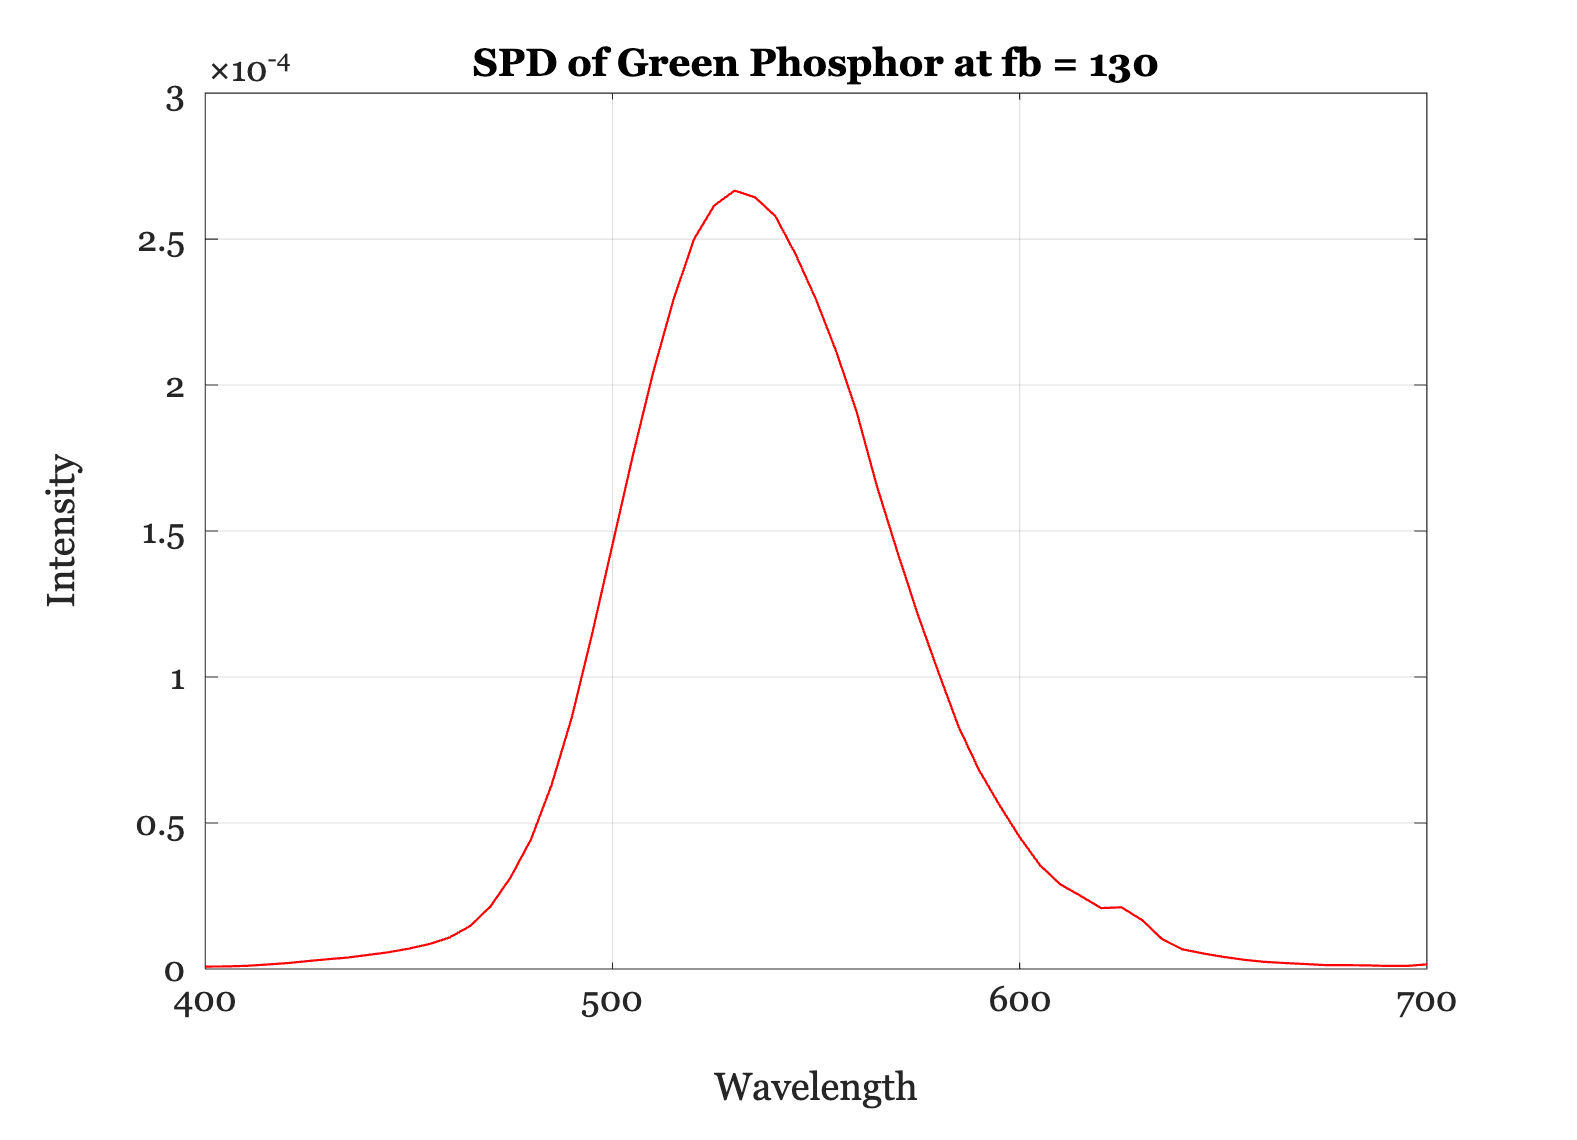

emitted = phosphors(:,2)*monitorGam(130,2);
plot(wavelength,emitted), grid on
xlabel('Wavelength')
ylabel('Intensity')
title('SPD of Green Phosphor at fb = 130');

Frequently, we are interested in how to set the frame-buffer level in order to obtain a given linear output intensity.  To determine this, we must calculate the inverse of the "gamma" function.  If we have fit a simple polynomial to the gamma function, then we can calculate the frame-buffer setting by inverting the function.  So that given a linear intensity, l, we can calculate the frame-buffer value as


$$\textrm{fb}=I^{\left(\frac{1}{\gamma }\right)}$$


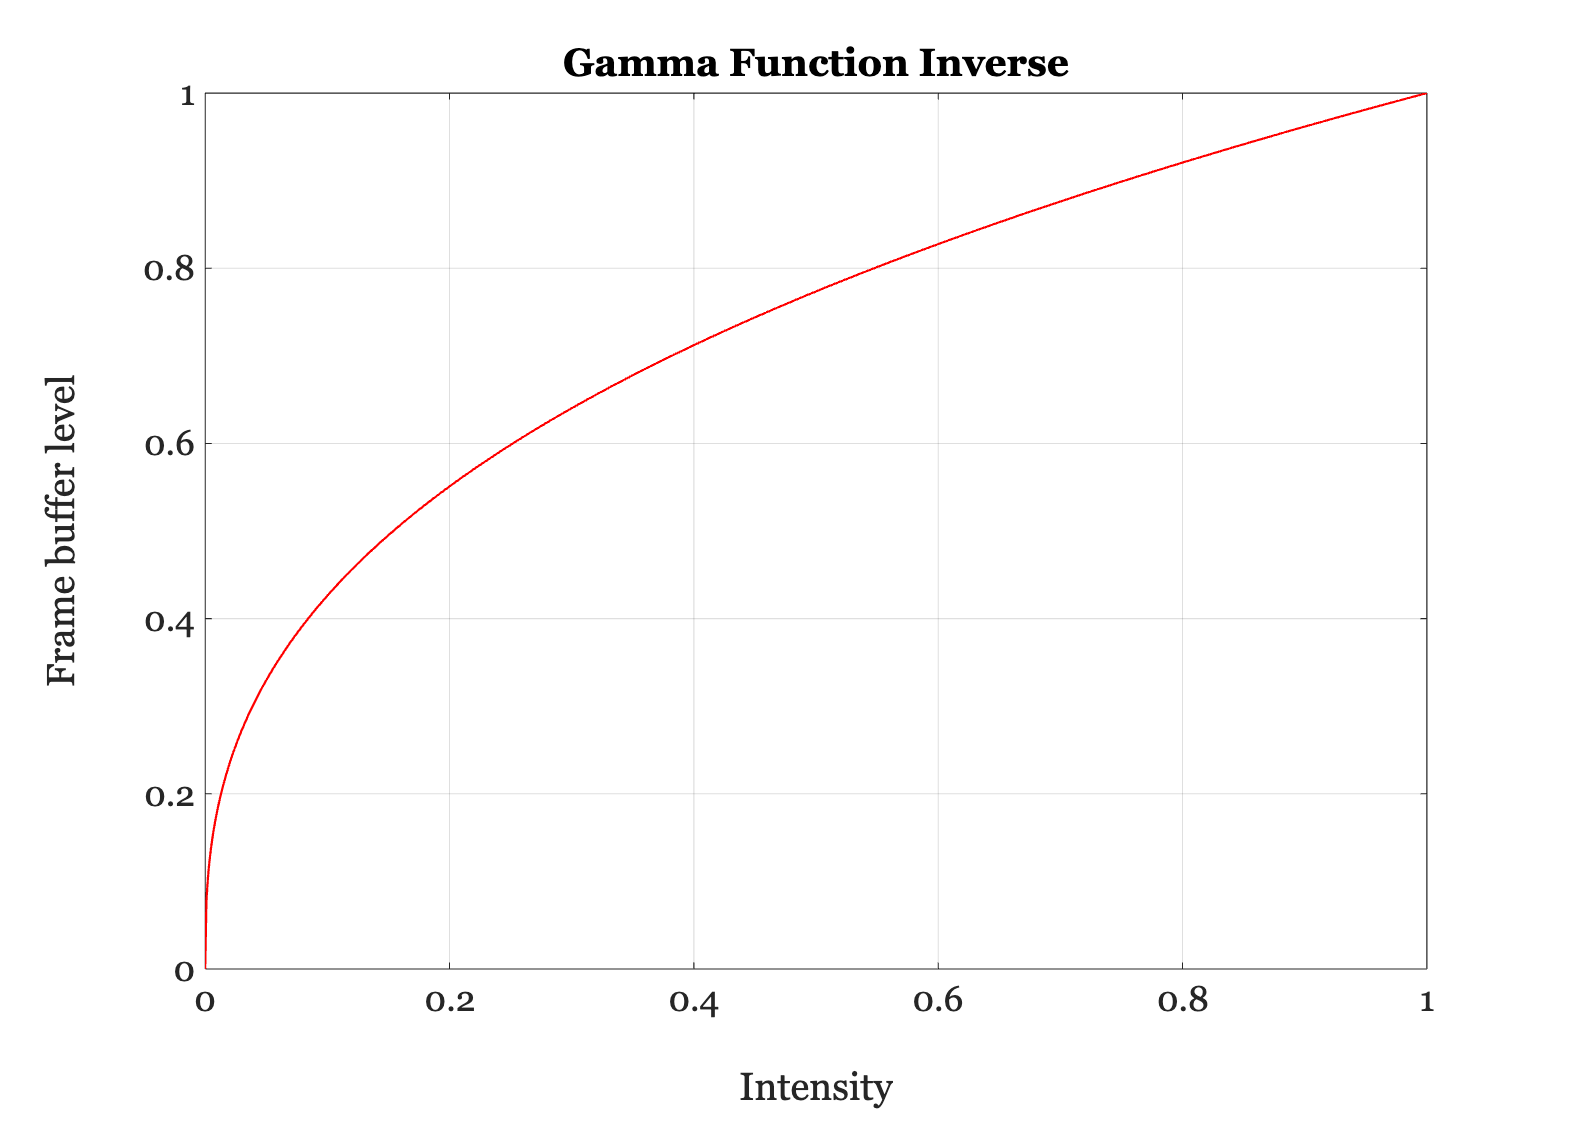

ieNewGraphWin;
intensity = 0:.001:1;
predFB = intensity.^(1/2.7);
plot(intensity,predFB)
xlabel('Intensity'); ylabel('Frame buffer level')
title('Gamma Function Inverse');
grid on

Another way to perform this calculation is by creating a look-up table that inverts the gamma function.  You should take a look at the code in the function "mkInvGammaTable" to see how Xuemei Zhang and I create inverse gamma look-up table functions.  To see the code enter "type  mkInvGammaTable"

invGamTable = mkInvGammaTable(monitorGam,1000);

Gamma table 1 NOT MONOTONIC.  We are adjusting.
Gamma table 2 NOT MONOTONIC.  We are adjusting.
Gamma table 3 NOT MONOTONIC.  We are adjusting.


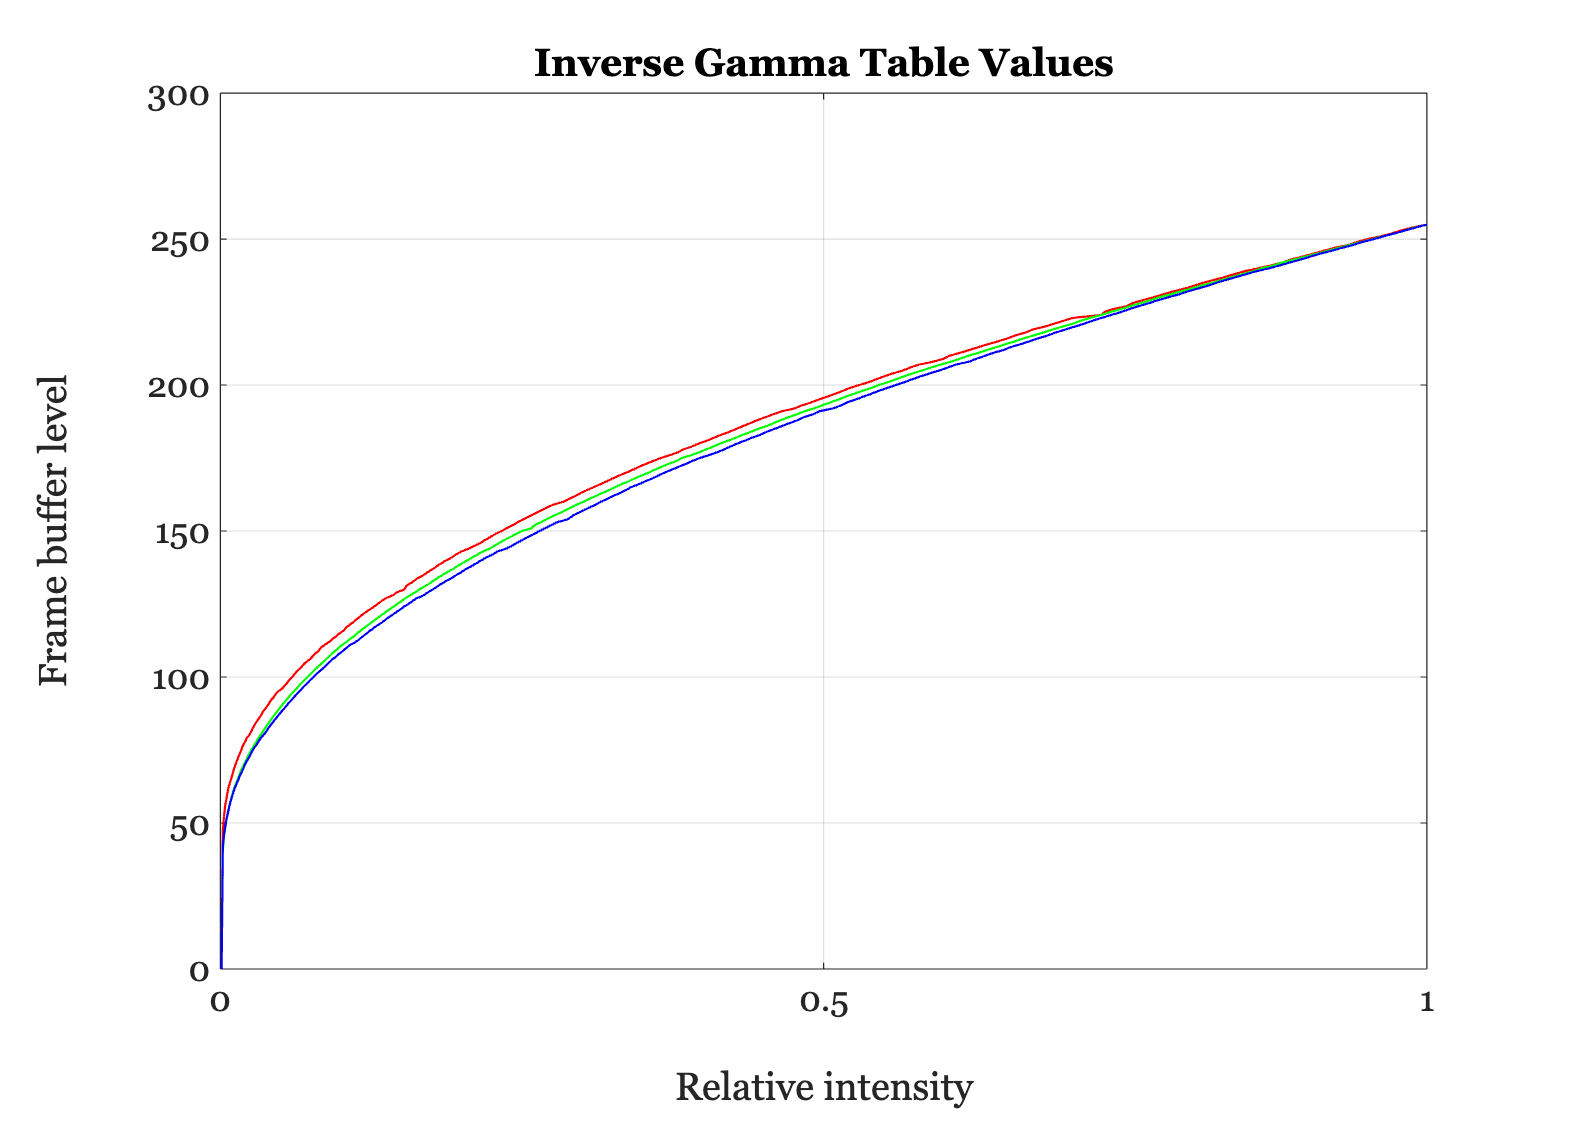

plot((1:1000)/1000,invGamTable), grid on
xlabel('Relative intensity')
ylabel('Frame buffer level')
title('Inverse Gamma Table Values');

(We make invGamTables with more than 8 bits of resolution because some of the frame buffers we have in the lab are 10 bits.

To look up the frame buffer value that will produce a particular linear intensity, then, we round the intensity to 1 part in a thousand (because there are a 1000 levels in the inverse table) and then use that as an index.  For example, to calculate the frame buffer values that generate linear intensities of [.1 .3 .5 .7 .9] we calculate as

intensity = (.1:.2:.9);
intensityX = round(intensity*1000)

intensityX =    100   300   500   700   900


fb = round(invGamTable(intensityX,1))

fb =    115
   163
   196
   222
   244


Now, let's see how well we did.  Here are the intensities we will obtain with these frame buffer values.

obtainedIntensity = monitorGam(fb,1)

obtainedIntensity =     0.0950
    0.2935
    0.4952
    0.6907
    0.8870


We can plot the obtained and desired intensities in a graph. We are close, but because of the quantization of the device we do not obtain the exact linear intensities.

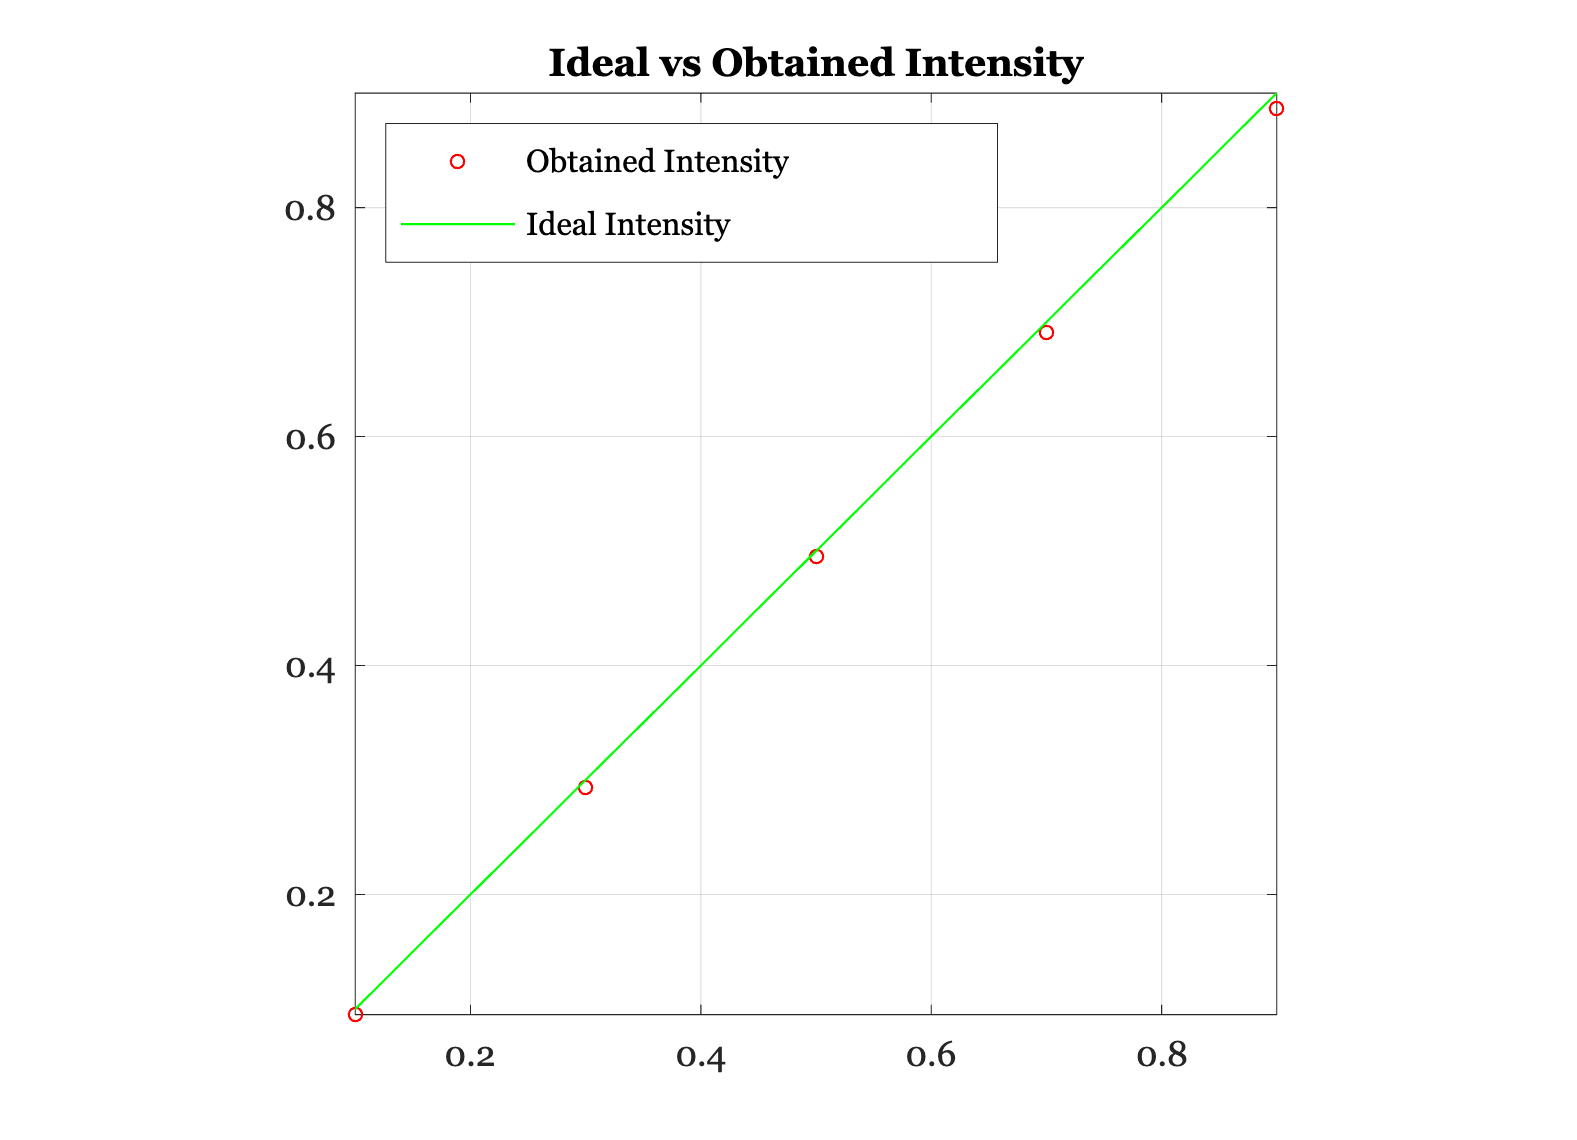

plot(intensity, obtainedIntensity, 'o', intensity, intensity,'-'), grid on
axis equal, axis square, axis tight
set(gca,'xtick',(0:.2:1),'ytick',(0:.2:1))
legend('Obtained Intensity', 'Ideal Intensity', 'Location', 'NorthWest');
title('Ideal vs Obtained Intensity');

## Computing xy-chromaticity coordinates

The monitor is also described in terms of several different chromaticity coordinate measurements, namely its "white point" and the gamut of colors that it can reach. The white point is the chromaticity coordinates of the display when all three phosphors are set to maximum intensity. These can be computed as

% We put the XYZ values into the columns (note the transpose)
maxXYZ = ieXYZFromEnergy(phosphors',wavelength(:))';

whitePoint = chromaticity(sum(maxXYZ,2)')'

whitePoint =     0.2849
    0.3037



% The (x,y) chromaticity coordinates of the phosphors can be
% computed individually as

xyMonitor = chromaticity(maxXYZ')'

xyMonitor =     0.6237    0.2902    0.1490
    0.3430    0.6095    0.0757


We can build a graph describing the chromaticity coordinates of the phosphors and the white point by first computing the xy coordinates of the spectrum.  Remember that the rows of xyz contain the XYZ values of each spectral light.  So, we can compute the chromaticity of the spectral lights as

xySpectrum = chromaticity(XYZ)';

Now, we plot these values and turn on hold.  Any light is a mixture of spectral lights, so these values define an outer boundary for where any physical light can fall.

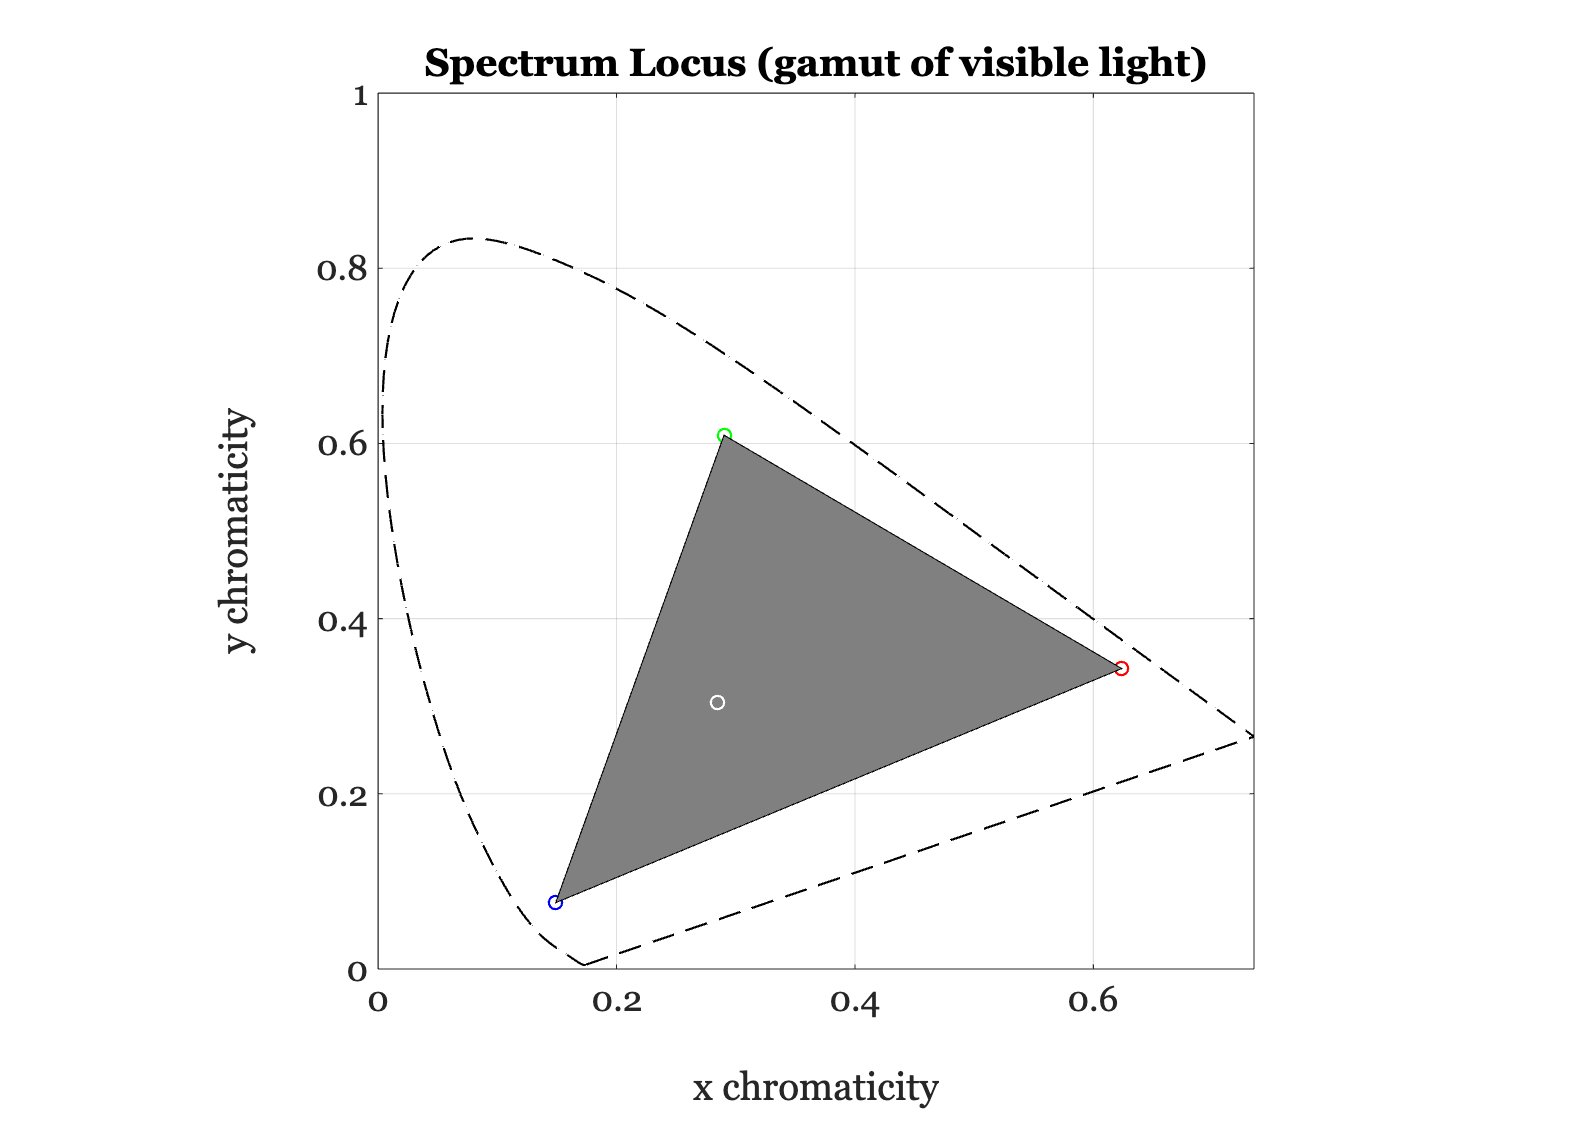

plotSpectrumLocus;  % Read this routine
axis equal, axis square
grid on, xlabel('x-chromaticity'), ylabel('y-chromaticity')
title('Spectrum Locus (gamut of visible light)');
hold on

% Overlay the xy coordinates of the three monitor phosphors on
% top of the graph

plot(xyMonitor(1,1),xyMonitor(2,1),'ro');
plot(xyMonitor(1,2),xyMonitor(2,2),'go');
plot(xyMonitor(1,3),xyMonitor(2,3),'bo');

% and place a patch over the region where sums of the phosphors
% can fall.  This is called the "gamut" of the display

p = patch(xyMonitor(1,:), xyMonitor(2,:), [.5 .5 .5]);

% Finally, add in the chromaticity coordinate of the white point
% and label the axes.

plot(whitePoint(1),whitePoint(2),'wo');
xlabel('x chromaticity'), ylabel('y chromaticity')
hold off

Notice that the white point coordinates are not at the middle of the gamut.  The position of the white point depends on the sum of the (X,Y,Z) values from each of the phosphors.  These are unequal, with the green and blue being the largest.  Hence, the white point is closer to these two corners of the gamut

sum(maxXYZ)

ans =    61.7836  110.1562  158.3428


## ISET makes it easy to plot the gamut, by the way

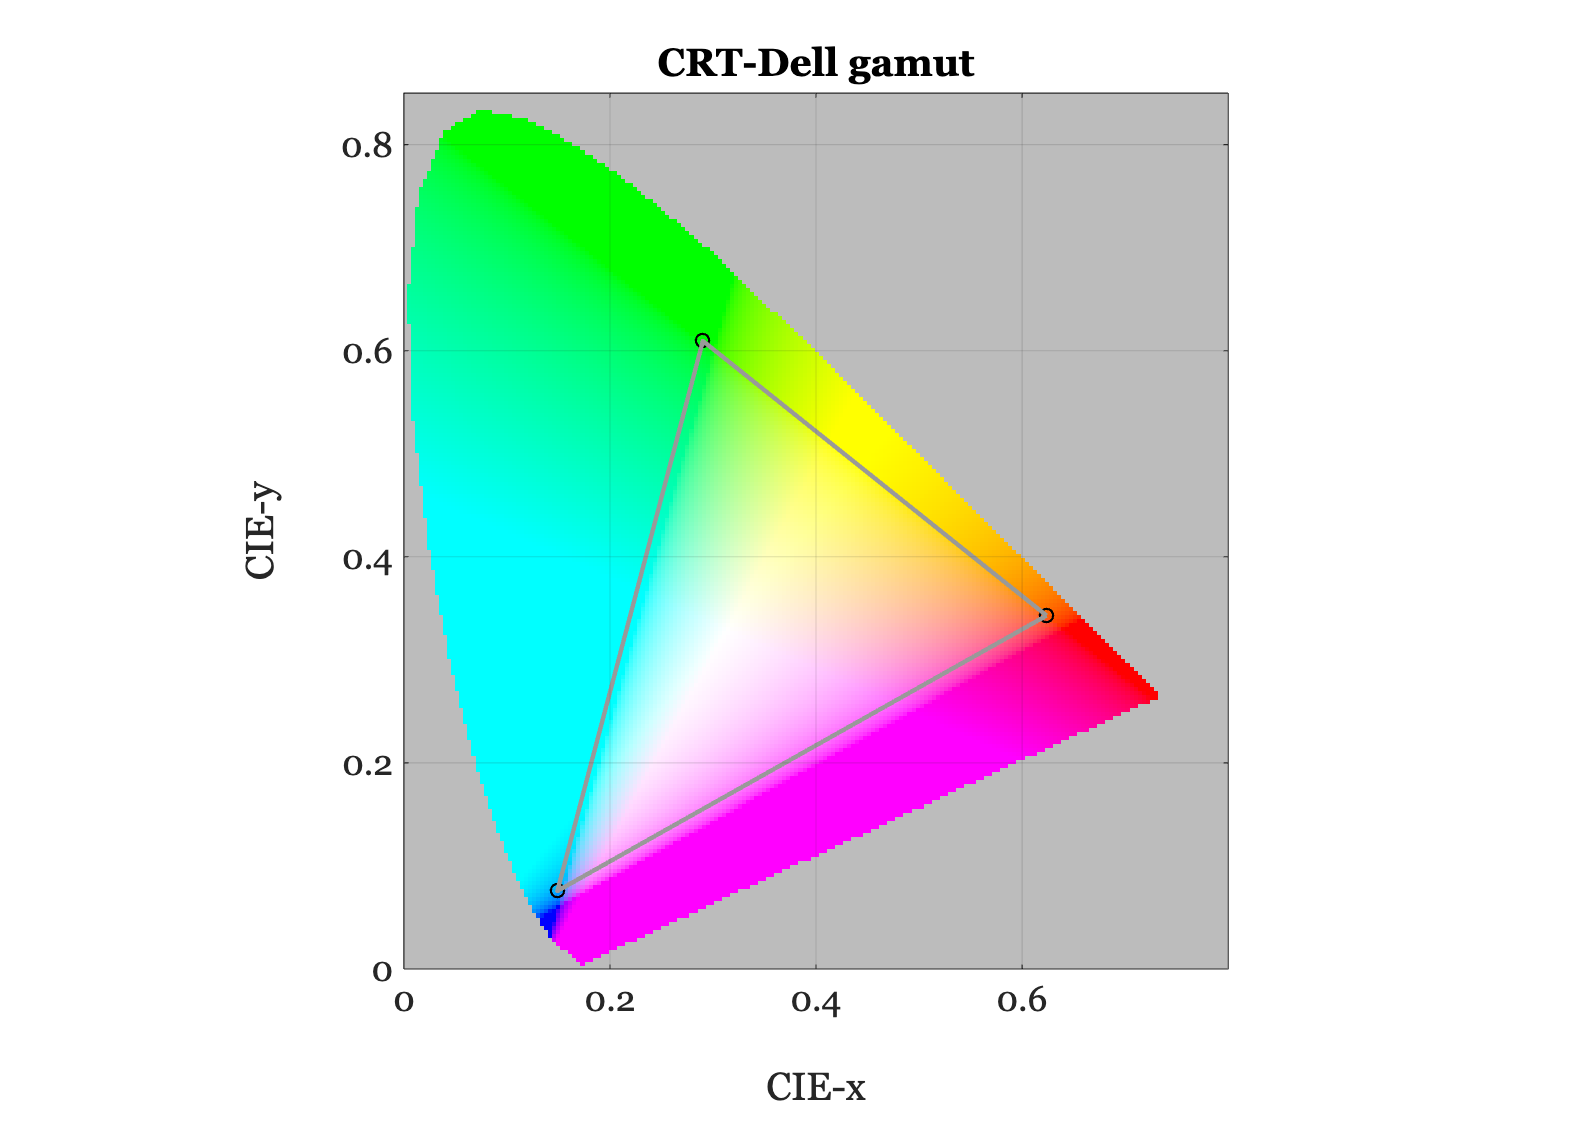

% These ideas are all embedded in the existing plotting routines. But the
% point of this script is to show you the ideas, not to plot the gamut.
displayPlot(d,'gamut');
title(sprintf('%s gamut',displayGet(d,'name')));

## TUTORIAL QUESTIONS

USING THE COLOR MATCHING FUNCTIONS

Consider a color matching experiment using a CRT monitor with phosphor spectral power distributions (SPD) given by 'phosphors' in cMatch/monitor.mat

a) Using the CIE-XYZ method, calculate what phosphor intensities you will need to match a monochrome light at 550nm. What phosphor intensities are needed to match a monochrome light at 430nm?

b) Plot the SPD of the phosphors that would make this match. Why are these intensities not physically realizable?

c) If you wanted to perform an experiment to test the predicted match what could you do to arrange the viewing conditions?

COLOR MONITOR CALIBRATION AND CHROMATICITY

a) Let the SPDs of the three phosphors of a color monitor be R, G, and B. Let the value of a pixel be written as a vector x = [r,g,b], where r, g, and b are between 0 and 1.

Write the matrix equation that expresses the SPD of a monitor pixel displaying the pixel x. (Ignore gamma correction)

b) How do the set of spectral power distributions emitted from a pixel compare with the spectral power distributions that are possible in the environment?

c) Typical monitors can modulate the linear phosphor intensity at 256 levels (8-bits). Suppose that you could modulate the phosphor intensities at 16-bit accuracy. Would this monitor produce better images? If you are not sure, then state what you need to know about the human visual system to decide whether the improvement is worthwhile.

d) Suppose that you are able to build a monitor with a fourth phosphor, not just the three that are usually built. In what sense would this monitor be better than a three-primary monitor? If you could set the x-y chromaticity of the phosphor, how would you design it to achieve the best monitor performance? You may want to sketch or plot a chromaticity diagram to show what you mean.

## Optional questions

Suppose you are an LCD manufacturer, and you know that if you had an ideal LCD, each of the R,G,B color channels would emit light according to the SPD given in monitors.mat. We have already plotted the color gamut of such a monitor.

In a real LCD display, the LC gates are not able to block 100% of the light from the backlight. Suppose that due to such leakage, the contrast ratio between a fully black and fully white display is 100:1. Plot the gamut of colors for this display and explain what happens.